% CONSTRAINT DIAGRAM TO FINDOUT WING LOADING

%AUTHOR: MONISHA VIJAYAN (AE25M037)

rho_0=1.225;
rho_alt=1.20;
rho_abs=1.19;
sigma_ceil=(rho_alt/rho_0);
sigma_ceil1=(rho_abs/rho_0);
g=9.81;
V_max=24;
V_stall=10;
CD0=0.025;
AR=9.686;
e=0.8;
S=0.413;
K=1/(pi*e*AR);
eta_p=0.77;
ROC=24.4720*sind(8);
L_D_max=15.54;
R_min=20;
S_TO=20;
ROC_ceil=5;
ROC_ceil1=0;
mu=0.04;
CL_max=((L_D_max)*(2*sqrt(CD0*K)))/0.8

CL_max = 1.2450

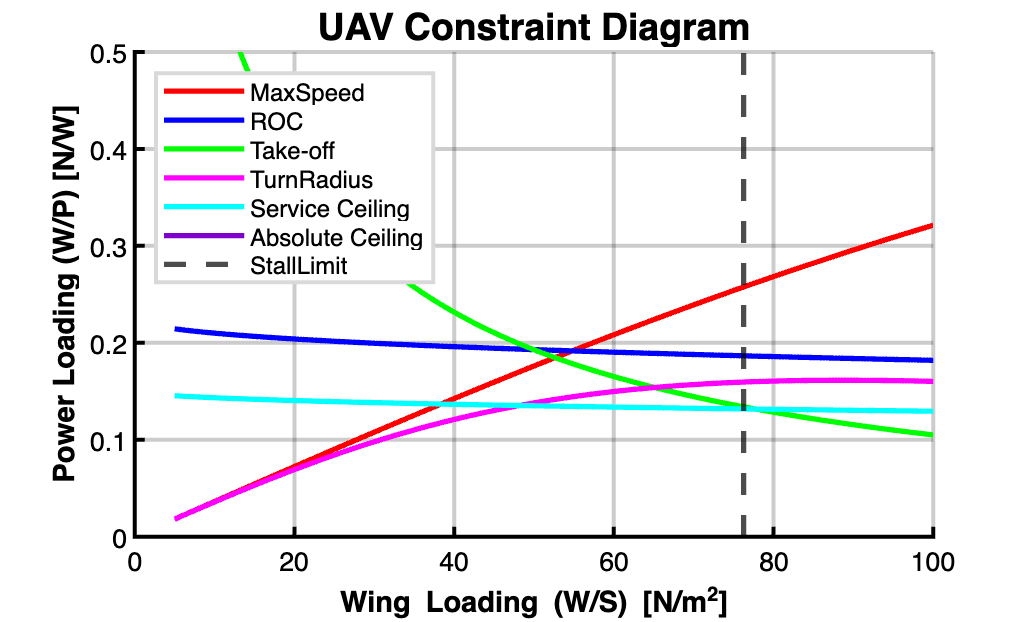

%CL_max=1.5;
WS=linspace(5,100,500);
% Stalling speed
WS_stall=0.5*rho_0*V_stall^2*CL_max;
% Maximum speed
WP_Vmax=eta_p./((0.5*rho_0*V_max^3*CD0./WS)+(2*K.*WS./(rho_0*V_max)));
% ROC
term_ROC=(1.155/(L_D_max))*sqrt((2.*WS)./(rho_alt*sqrt(3*CD0/K)));
WP_ROC=eta_p./(ROC+term_ROC);
% Takeoff
V_TO=1.2*V_stall;
CDG=CD0+K*(mu/(2*K))^2;
exp_term=exp(0.6*rho_0*g*CDG*S_TO./WS);
WP_STO=((1-exp_term)./(mu-(mu+CDG/CL_max).*exp_term)).*(eta_p/V_TO);
% Minimum Turn Radius
n=sqrt((V_max^2/(g*R_min))^2+1);
q_max=0.5*rho_0*V_max^2;
PW_Turn=(V_max/eta_p).*((q_max*CD0./WS)+(K*n^2.*WS./q_max));
WP_Turn=1./PW_Turn;
%Service ceiling
term_ceil=(1.155/(L_D_max*eta_p))*sqrt((2.*WS)./(rho_alt*sqrt(3*CD0/K)));
WP_Ceiling=sigma_ceil./((ROC_ceil/eta_p)+term_ceil);
%Absolute ceiling
term_ceil=(1.155/(L_D_max*eta_p))*sqrt((2.*WS)./(rho_abs*sqrt(3*CD0/K)));
WP_Ceiling1=sigma_ceil1./((ROC_ceil1/eta_p)+term_ceil);
figure
fig=figure('Color','w');set(gcf,'InvertHardcopy','off');
ax=gca;ax.Color='w';ax.XColor='k';ax.YColor='k';ax.GridColor='k';ax.GridAlpha=0.2;ax.LineWidth=1.5;hold on;grid on;
plot(WS,WP_Vmax,'r','LineWidth',2,'DisplayName','MaxSpeed');
plot(WS,WP_ROC,'b','LineWidth',2,'DisplayName','ROC');
plot(WS,WP_STO,'g','LineWidth',2,'DisplayName','Take-off');
plot(WS,WP_Turn,'m','LineWidth',2,'DisplayName','TurnRadius');
plot(WS,WP_Ceiling,'c','LineWidth',2,'DisplayName','Service Ceiling');
plot(WS,WP_Ceiling1,'Color',[0.5 0 0.8],'LineWidth',2,'DisplayName','Absolute Ceiling');
xline(WS_stall,'--k','LineWidth',2,'DisplayName','StallLimit');
xlabel('Wing Loading (W/S) [N/m^2]','FontWeight','bold');
ylabel('Power Loading (W/P) [N/W]','FontWeight','bold');
title('UAV Constraint Diagram','FontSize',14,'Fontweight','bold','Color','k');
legend('Location','northwest','TextColor','k','Color','w');
ylim([0,0.5])
hold off;



% NEW SURFACE AREA
b=2;
W_S=64;
W=68.516;
S_new=W/(W_S)

S_new = 1.0706

AR=(b^2)/S_new

AR = 3.7364